# **Tutorial: Gradient Descent**

**Numerical Programming: Y.-K. Kim**

Mod. 2024.11

## Problem Statement

Solve the minimum value and the minimum point(x) of the given function by using Gradient Descent.

# **Exercise 1**

**Find the ****point**** (x*********) that minimize ****the ****function ****L(x)**

L(x)=x^2-4x+6

Use gradient descent with initial point at x0=0

Use the learning rate as

- η=0.25

- η=1

- η=0.05

### Define Loss Function

L(x)=x^2-4x+6

close all, clear all

type myLoss_ex1_student

function L = myLoss_ex1_student(x)
    L= x.^2-4.*x+6;
end



    


### Define Gradient of Loss Function

type myLossGrad_ex1_student

function dL= myLossGrad_ex1_student(x)
    dL=2.*x-4;
end


### Gradient Descent 

%% Gradient Descent
itrMax=20;
eta=0.25;  %eta=1.01   %eta=0.05

x0=0;
x=x0;

for k=1:itrMax
    % Calculate Loss    
    loss=myLoss_ex1_student(x);
    loss_ex1(k,:)=[x,loss];

    % Update x with Gradient Descent
    % [TO-DO] 
    grad_L=myLossGrad_ex1_student(x); %L'(x)
    % x=______________
    x=x-eta*grad_L;

    fprintf('Iter k=%d \t x=%f \t loss=%f \n', k, x, loss)
end

Iter k=1 	 x=1.000000 	 loss=6.000000 
Iter k=2 	 x=1.500000 	 loss=3.000000 
Iter k=3 	 x=1.750000 	 loss=2.250000 
Iter k=4 	 x=1.875000 	 loss=2.062500 
Iter k=5 	 x=1.937500 	 loss=2.015625 
Iter k=6 	 x=1.968750 	 loss=2.003906 
Iter k=7 	 x=1.984375 	 loss=2.000977 
Iter k=8 	 x=1.992188 	 loss=2.000244 
Iter k=9 	 x=1.996094 	 loss=2.000061 
Iter k=10 	 x=1.998047 	 loss=2.000015 
Iter k=11 	 x=1.999023 	 loss=2.000004 
Iter k=12 	 x=1.999512 	 loss=2.000001 
Iter k=13 	 x=1.999756 	 loss=2.000000 
Iter k=14 	 x=1.999878 	 loss=2.000000 
Iter k=15 	 x=1.999939 	 loss=2.000000 
Iter k=16 	 x=1.999969 	 loss=2.000000 
Iter k=17 	 x=1.999985 	 loss=2.000000 
Iter k=18 	 x=1.999992 	 loss=2.000000 
Iter k=19 	 x=1.999996 	 loss=2.000000 
Iter k=20 	 x=1.999998 	 loss=2.000000 


### Plot  output

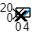

%% Plot L(x)
i=-1:0.5:6;
L=myLoss_ex1_student(i);

figure(1)
plot(i,L)
hold on
plot(loss_ex1(:,1), loss_ex1(:,2), 'k-','MarkerSize',10,'Marker','x','Color',[0 0 0])    

# **Exercise 2**

**Find the ****point****s (x*********, y*********) that minimize ****the ****function ****L(****x,y****)**

### Define Loss Function

close all, clear all  
clc

% For meshgrid plot
L_ex2=@(x,y) 3*(x-2).^2+(y-2).^2;  

type myLoss_ex2_student

function L = myLoss_ex2_student(W)

    L=0;
    x=W(1);
    y=W(2);
    
    % [TO-DO] Loss Function 
    % L=_______________
    L=3*(x-2)^2-(y-2)^2;

end



    


### Define Gradient of Loss Function

%% Calculate dL/dw
%x=W(1)
%y=W(2)
%grad_L=@(x,y) [6*(x-2); 2*(y-2)];

type myLossGrad_ex2_student

function dL= myLossGrad_ex2_student(W)

    x=W(1);
    y=W(2);
    dL= [0;0];

    % [TO-DO] Gradident of Loss Function 
    % dL= [________;
    %     _________];
    dL=[6*(x-2);
        2*(y-2)];

end


### Gradient Descent 

 where 

Use x0=[-2, -2].  Use the learning rate as η=0.25

%% Gradient Descent
itrMax=20;
eta=0.25;
W0=[-2; -2];
W=W0;

for k=1:itrMax
    % Calculate Loss    
    loss=myLoss_ex2_student(W);
    loss_ex2(k,:)=[W(1),W(2),loss];

    % Update W with Gradient Descent
    % [TO-DO] 
    grad_L=myLossGrad_ex2_student(W);
    W=W-eta.*grad_L;

    fprintf("iter =%d \t x=%0.3f\t y=%0.3f\t loss=%0.3f\n",k,W(1),W(2),loss)
end

iter =1 	 x=4.000	 y=0.000	 loss=32.000
iter =2 	 x=1.000	 y=1.000	 loss=8.000
iter =3 	 x=2.500	 y=1.500	 loss=2.000
iter =4 	 x=1.750	 y=1.750	 loss=0.500
iter =5 	 x=2.125	 y=1.875	 loss=0.125
iter =6 	 x=1.938	 y=1.938	 loss=0.031
iter =7 	 x=2.031	 y=1.969	 loss=0.008
iter =8 	 x=1.984	 y=1.984	 loss=0.002
iter =9 	 x=2.008	 y=1.992	 loss=0.000
iter =10 	 x=1.996	 y=1.996	 loss=0.000
iter =11 	 x=2.002	 y=1.998	 loss=0.000
iter =12 	 x=1.999	 y=1.999	 loss=0.000
iter =13 	 x=2.000	 y=2.000	 loss=0.000
iter =14 	 x=2.000	 y=2.000	 loss=0.000
iter =15 	 x=2.000	 y=2.000	 loss=0.000
iter =16 	 x=2.000	 y=2.000	 loss=0.000
iter =17 	 x=2.000	 y=2.000	 loss=0.000
iter =18 	 x=2.000	 y=2.000	 loss=0.000
iter =19 	 x=2.000	 y=2.000	 loss=0.000
iter =20 	 x=2.000	 y=2.000	 loss=0.000


### Plot  output

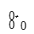

% Plot 3D
u = -8:0.5:8;
[X,Y] = meshgrid(u);

figure(2)
surf(X,Y,L_ex2(X,Y))
ylabel('Y');
xlabel('X');
zlabel('L(x,y)');

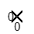



% Plot 2D Contour
figure(3)
contour(X,Y,L_ex2(X,Y))
hold on
plot(loss_ex2(:,1),loss_ex2(:,2),'k-','MarkerSize',10,'Marker','x','Color',[0 0 0]);
ylabel('Y');
xlabel('X');

# **Exercise 3**

Linear Regression using Gradient Descent

## Problem Statement

An experiment is conducted that measures the pressure of a gas by heating it in a closed chamber. 

T=[30	40	50	60	70	80];

P=[1.05	1.07	1.09	1.14	1.17	1.21];

Based on Charles's law for ideal gas P=kT, where k is a constant.

The best fit curve is   P=a0+a1(T)

**Predict** the pressure if the temperature is increased to 150C.

### Prepare Train Dataset

close all, clear all

%% Dataset
% Input data: T
T_raw=[30	40	50	60	70	80];

% Ouput Label: P
P_raw=[1.05	1.07	1.09	1.14	1.17	1.21];


### Normalize Input Data

Normalize the input data only (T for this example)

- See what happends if you don't normalize T

- Output value P can also be normalized. But, here it is not necessary

Here, we used min-max normalization

% Normalize Input data: T
T=normalize(T_raw);

% Use the raw data of Output Label: P
P=P_raw;

### Define Loss Function

Loss Function

type myLoss_ex3_student

function E = myLoss_ex3_student(W,X,Y)

    %% Initialization
    a0=W(1);
    a1=W(2);
    m=length(X);
    E=0;

    %% Loss Function
    % [TO-DO] Gradident of Loss Function 
    % E= __________
    for i=1:m
        E=E+(Y(i)-(a1*X(i)+a0))^2;
    end
    
    E=E/m;

end



    


### Define Gradient of Loss Function

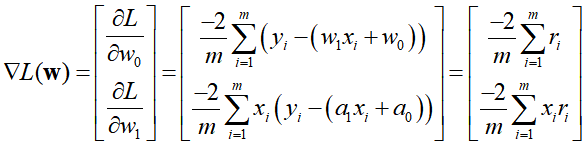

type myLossGrad_ex3_student

function dE= myLossGrad_ex3_student(W,X,Y)

    %% Initialization
    a0=W(1);
    a1=W(2);
    m=length(X);
    dE=[0;0];
    
    %% Loss Function
    % [TO-DO] Gradident of Loss Function 
    % dE= __________

    for k=1:m
        r=(Y(k)-(a1*X(k)+a0));
        dE=dE+[r;X(k)*r];    
    end
    dE=-2./m.*(dE);
end



### Gradient Descent (Train model)

True values:  w0=0.9410,  w1=0.0033

%% Gradient Descent
itrMax=300;
eta=0.1;
 
W0=[0; 0];
W=W0;
loss=0;

loss_ex3=zeros(itrMax,3);
loss_ex3(1,:)=[W(1),W(2),loss];

% Gradien Descent
for k=1:itrMax
    loss=myLoss_ex3_student(W,T,P);
    loss_ex3(k,:)=[W(1),W(2),loss];

    grad_L=myLossGrad_ex3_student(W,T,P);
    W=W-eta*grad_L;

    if(~mod(k,10))
        fprintf("Iter =%d \t w0=%0.3f\t w1=%0.3f\t loss=%0.8f\n",k,W(1),W(2),loss)
    end
end

Iter =10 	 w0=0.868	 w1=-0.339	 loss=0.04055190
Iter =20 	 w0=0.960	 w1=-0.273	 loss=0.02387772
Iter =30 	 w0=1.003	 w1=-0.200	 loss=0.01651239
Iter =40 	 w0=1.037	 w1=-0.139	 loss=0.01143313
Iter =50 	 w0=1.065	 w1=-0.088	 loss=0.00792247
Iter =60 	 w0=1.088	 w1=-0.045	 loss=0.00549597
Iter =70 	 w0=1.108	 w1=-0.010	 loss=0.00381881
Iter =80 	 w0=1.124	 w1=0.019	 loss=0.00265959
Iter =90 	 w0=1.138	 w1=0.044	 loss=0.00185836
Iter =100 	 w0=1.149	 w1=0.064	 loss=0.00130456
Iter =110 	 w0=1.158	 w1=0.081	 loss=0.00092179
Iter =120 	 w0=1.166	 w1=0.095	 loss=0.00065722
Iter =130 	 w0=1.172	 w1=0.107	 loss=0.00047436
Iter =140 	 w0=1.177	 w1=0.116	 loss=0.00034796
Iter =150 	 w0=1.182	 w1=0.125	 loss=0.00026060
Iter =160 	 w0=1.186	 w1=0.131	 loss=0.00020022
Iter =170 	 w0=1.189	 w1=0.137	 loss=0.00015849
Iter =180 	 w0=1.191	 w1=0.141	 loss=0.00012964
Iter =190 	 w0=1.193	 w1=0.145	 loss=0.00010970
Iter =200 	 w0=1.195	 w1=0.148	 loss=0.00009592
Iter =210 	 w0=1.197	 w1=0.151	 loss=0.000


% Unormalize the input data T 
W_opt= unnormalize(W,T_raw)

W_opt =     0.9436    0.0032




% Compare with ground-truth value
W_mat=polyfit(T_raw,P_raw,1)

W_mat =     0.0033    0.9410


### Predict (Test)

T_test=150;
P_test=W_opt(1)+W_opt(2).*T_test

P_test = 1.4290

### Plot  output

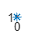

T_opt=30:10:150;
P_opt=W_opt(1)+W_opt(2).*T_opt;

figure()
plot(T_raw,P_raw, '*')
hold on
plot(T_opt,P_opt)
hold on
plot(T_test,P_test)
xlabel('Temperature (C)')
ylabel('Pressure (atm)')